# Double Integrator Reach-Avoid Via Dynamic Programming

This example demonstrates how to use the SReachTools toolbox to solve a terminal-hitting time reach-avoid problem using [dynamic programming](https://doi.org/10.1016/j.automatica.2010.08.006).

In this example, we analyze the following problems via dynamic programming for a stochastic system with known dynamics:

- **the terminal-hitting time reach-avoid problem **posed as the stochastic reachability of a target tube problem

- **stochastic reachability of a moving target tube**

The terminal-hitting time reach-avoid problem computes a controller that maximizes the probability of reaching a target, `target_set`, at a time horizon, `N`, while maintaining the system in a set of safe states, `safe_set`. This problem is generalized as the problem of stochastic reachability of a target tube --- maximize the probability of staying within a target tube. For reach-avoid problems, the target tube has a specific structure. Finally, we implement a dynamic programming solution to the problem of stochastic reachability of a general target tube.

## Double Integrator

In this example we use a discretized double integrator dynamics given by:


$$  x_{k+1} = \left[ \begin{array}{cc}
    1 & T \\
    0 & 1
  \end{array}\right] x_{k} + \left[\begin{array}{c}
    \frac{T^{2}}{2} \\
    T
  \end{array}\right] u_{k} + w_{k}$$


where $T$ is the discretization time-step, and $w_{k}$ is the stochastic disturbance.

## Notes about this Live Script:

- **MATLAB dependencies**: This Live Script uses MATLAB's  [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html). 

- **External dependencies**: This Live Script uses Multi-Parameteric Toolbox ([MPT](http://people.ee.ethz.ch/~mpt/3/)). 

- Make sure that `srtinit` is run before running this script.

This Live Script is part of the SReachTools toolbox. License for the use of this function is given in [https://github.com/unm-hscl/SReachTools/blob/master/LICENSE](https://github.com/unm-hscl/SReachTools/blob/master/LICENSE).

## Setup the system

% discretization parameter
T = 0.25;

% define the system
sys = LtiSystem('StateMatrix', [1, T; 0, 1], ...
    'InputMatrix', [T^2/2; T], ...
    'InputSpace', Polyhedron('lb', -0.1, 'ub', 0.1), ...
    'DisturbanceMatrix', eye(2), ...
    'Disturbance', StochasticDisturbance('Gaussian', zeros(2,1), 0.01*eye(2)));

## Setup the target and safe sets

% safe set definition
safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);
target_set = Polyhedron('lb', [-0.5, -0.5], 'ub', [0.5, 0.5]);


## Setup the target tube

Target tube is a generalization of the reach problem. The reach avoid target-tube is created by setting the first $N-1$ sets in the tube as the `safe_set` and the final set as the `target_set`.

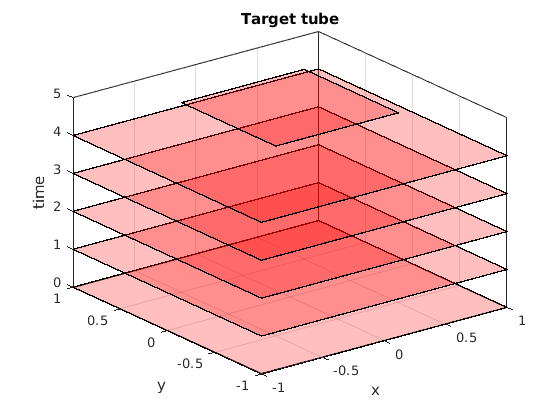

% time horizon
N = 5;
% in target tube for the viability problem is equivalent to a tube of repeating
% safe sets
target_tube = TargetTube('reach-avoid', safe_set, target_set, N+1);

% Plotting of target tube
figure()
hold on    
for time_indx=0:N
    target_tube_at_time_indx = Polyhedron('H',[target_tube(time_indx+1).A,zeros(size(target_tube(time_indx+1).A,1),1), target_tube(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(target_tube_at_time_indx, 'alpha',0.25);
end
axis([-1 1 -1 1 0 N]);    
box on;
grid on;
xlabel('x');
ylabel('y');
zlabel('time');
title('Target tube');

## Dynamic programming recursion via gridding

For dynamic programming, we need to create a grid over which we will perform the recursion

% need to create a state space grid and input space grid
ss_grid = SpaceGrid([-1, -1], [1, 1], 40);
in_grid = InputGrid(-1, 1, 3);

grid_probability = getDynProgSolForTargetTube(sys, ...
    ss_grid, in_grid, target_tube);

Computing V_4
Computing V_3
Computing V_2
Computing V_1
Computing V_0


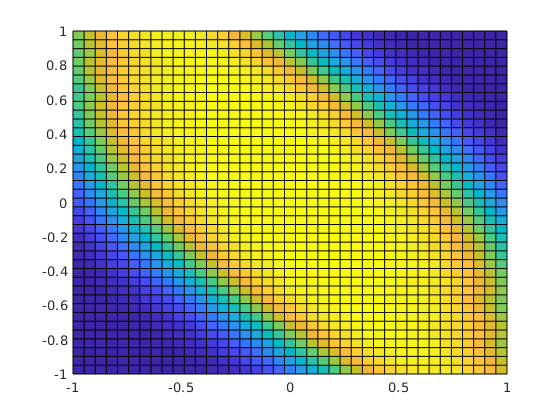


figure();
ss_grid.plotGridProbability(grid_probability);
view(0, 90)

## Reachability of a target tube for moving target problems

The advantage of target tube is that it allows for problem formulations in which we would like to reach a moving target.

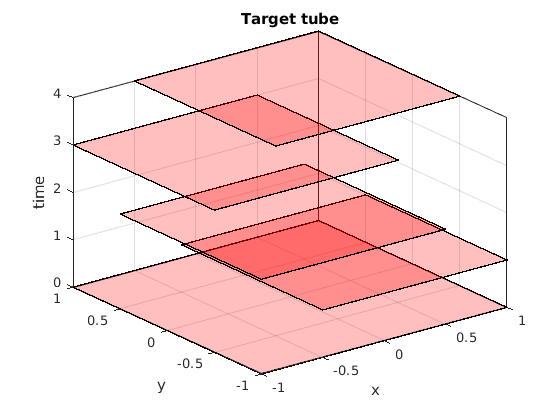

target_tube = TargetTube(Polyhedron('lb', [-1, -1], 'ub', [1, 1]), ...
    Polyhedron('lb', [-0.5, -1], 'ub', [1, 0.5]),...
    Polyhedron('lb', [-1, -1], 'ub', [0.5, 0.5]), ...
    Polyhedron('lb', [-1, -0.5], 'ub', [0.5, 1]), ...
    Polyhedron('lb', [-0.5, -0.5], 'ub', [1, 1]));
N=length(target_tube)-1;
% Plotting of target tube
figure()
hold on    
for time_indx=0:N
    target_tube_at_time_indx = Polyhedron('H',[target_tube(time_indx+1).A,zeros(size(target_tube(time_indx+1).A,1),1), target_tube(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(target_tube_at_time_indx, 'alpha',0.25);
end
axis([-1 1 -1 1 0 N]);
box on;
grid on;
xlabel('x');
ylabel('y');
zlabel('time');
title('Target tube');

## Dynamic programming solution on target tube

ss_grid = SpaceGrid([-1, -1], [1, 1], 40);
in_grid = InputGrid(-0.1, 0.1, 3);

grid_probability = getDynProgSolForTargetTube(sys, ...
    ss_grid, in_grid, target_tube);

Computing V_3
Computing V_2
Computing V_1
Computing V_0


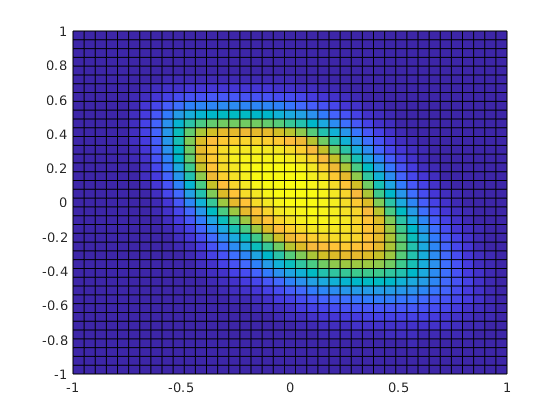


figure();
ss_grid.plotGridProbability(grid_probability);
view(0, 90)